% %code for regression based on linear gaussian process
% clear all; clc;
% randn('seed',0);
% rng default
% rng(1225)
% N = 100;
% nTrain = 20;
% nTest = N-nTrain;
% mean = 0;
% var = 1;
% w = mean + var.*randn(100,1);
% 
% B = [1,-2.3695,2.3140,-1.0547,0.1874];
% A = [0.0048,0.0193,0.0289,0.0193,0.0048];
% output = filter(A,B,w);
% 
% r=randperm(N);
% index=r(1:nTrain);
% 
% %%
% f = zeros(1,nTrain);
% f = output(index);
% x = 1:N;
% xtrain = x(index)';
% ytrain = f;
% diffI = setdiff(1:N,index);
% xtest = x(diffI)';
% ytest = output(diffI);
% meanfunc = {@meanSum, {@meanLinear, @meanConst}}; hyp.mean = [0; 0];
% covfunc = @covSEiso; hyp.cov = [0; 0];
% likfunc = @likGauss; hyp.lik = log(std(xtrain));
% hyp = minimize(hyp, @gp, -1000, @infExact, meanfunc, covfunc, likfunc, xtrain, ytrain);
% nlml = gp(hyp, @infExact, meanfunc, covfunc, likfunc, xtrain, ytrain)
% %%
% figure(1)
% [m, s2] = gp(hyp, @infExact, meanfunc, covfunc, likfunc, xtrain, ytrain, xtest);
% fi = [m+2*sqrt(s2); flipdim(m-2*sqrt(s2),1)]; 
% fill([xtest; flipdim(xtest,1)], fi, [0.95 0.95 0.95])
% hold on; plot(xtest, m, '--k', xtest,ytest,'or', LineWidth=1); plot(xtrain, ytrain, '+b', LineWidth=1)
% hold off;
% grid minor;
% legend('2\sigma boundary','Predicted Output','Test Data','Training Data');
% error1 = sum((m-ytest).^2)/length(m)

%code for Non-linear Gaussian Process for a model for which the output is corrupted by the white noise
plus AR(1) noise

ans =    175   193   145   164   142


clear all;  clc;
randn('seed',0);
rng default
rng(1225)
N = 200;
nTrain = 100;
nTest = N-nTrain;
mean = 0;
var = -2;
w = mean + var.*randn(N,1);
B = [1,-2.3695,2.3140,-1.0547,0.1874];
A = [0.0048,0.0193,0.0289,0.0193,0.0048];
output = filter(A,B,w);

r=randperm(N);
index=r(1:nTrain);
% while 1
%     index = unique(randi([1 N],nTrain,1));
%     if length(index)== nTrain
%         break;    
%     end
% end
diffI = setdiff(1:N,index);
%  w = 1:200; 
w1 = [w(1:end)'];
w2 = [0 w(1:end-1)'];
w3 = [0 0 w(1:end-2)'];
w4 = [0 0 0 w(1:end-3)'];
w5 = [0 0 0 0 w(1:end-4)'];
W = [w1;w2;w3;w4;w5];

f1 = [0 output(1:end-1)'];
f2 = [0 0 output(1:end-2)'];
f3 = [0 0 0 output(1:end-3)'];
f4 = [0 0 0 0 output(1:end-4)'];
f5 = [0 0 0 0 0 output(1:end-5)'];
F = [f1;f2;f3;f4;f5];
%F=zeros(5,200);

wg = 0.1*randn(N,1);
g = filter(1,[1,-0.2],wg);

X = [F;W];
x_train = X(:,index)';
x_test = X(:,diffI)';
Y = (output+g);
y_train = Y(index);
y_test = Y(diffI);

meanfunc = @meanLinear; hyp.mean = zeros(10,1);
covfunc = {@covSum, {@covSEiso, @covNoise}}; hyp.cov = [0; 0; 0];%non linear part worked out in covfunc
likfunc = @likGauss; hyp.lik = log(0.1);
hyp = minimize(hyp, @gp, -1000, @infExact, meanfunc, covfunc, likfunc, x_train, y_train);

Function evaluation      0;  Value 1.487079e+02
Function evaluation      6;  Value 1.183191e+02
Function evaluation      8;  Value 9.388591e+01
Function evaluation     11;  Value 4.773262e+01
Function evaluation     14;  Value 3.151840e+01
Function evaluation     15;  Value 1.714118e+01
Function evaluation     17;  Value 9.225393e+00
Function evaluation     18;  Value 1.548104e+00
Function evaluation     20;  Value -4.569286e+00
Function evaluation     22;  Value -7.851756e+00
Function evaluation     24;  Value -1.425695e+01
Function evaluation     26;  Value -2.615432e+01
Function evaluation     30;  Value -3.008559e+01
Function evaluation     32;  Value -4.007828e+01
Function evaluation     34;  Value -4.645527e+01
Function evaluation     36;  Value -4.992526e+01
Function evaluation     37;  Value -5.330755e+01
Function evaluation     39;  Value -5.766991e+01
Function evaluation     41;  Value -6.039711e+01
Function evaluation     43;  Value -6.237496e+01
Function evaluation     45; 

nlml = gp(hyp, @infExact, meanfunc, covfunc, likfunc, x_train, y_train)

nlml = -91.4954

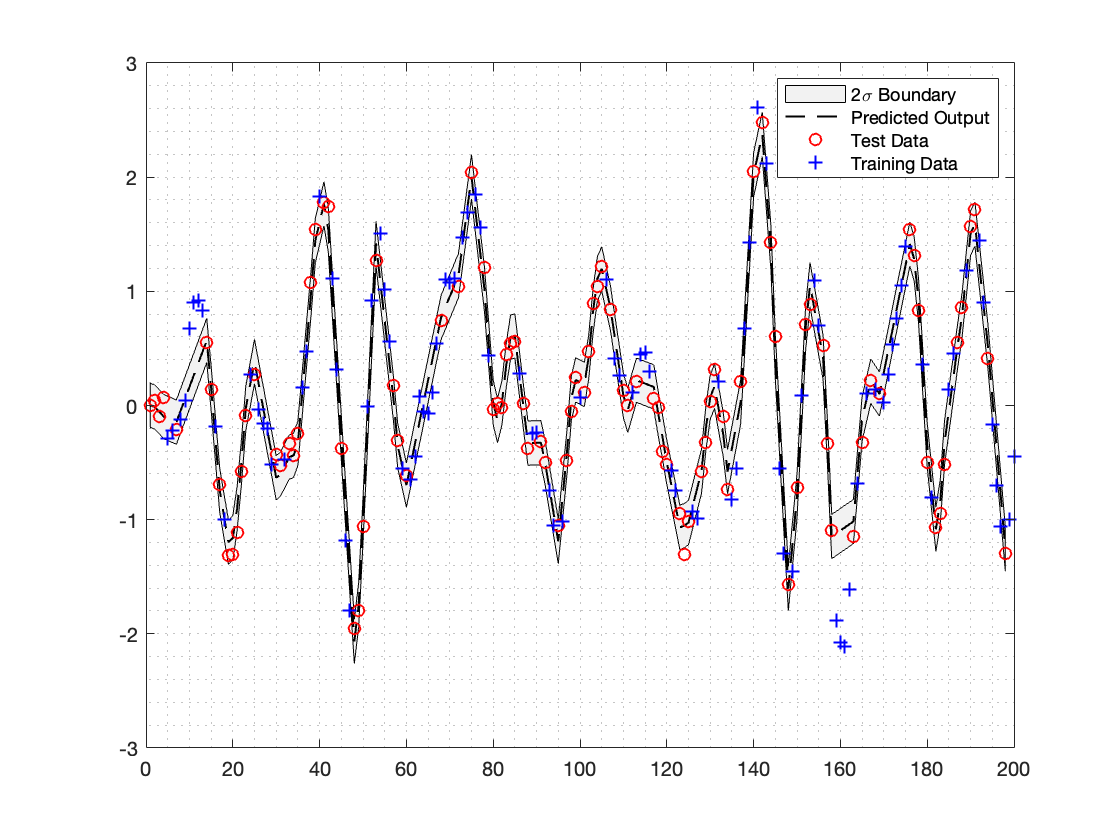

%%
figure(3);
[m s2] = gp(hyp, @infExact, meanfunc, covfunc, likfunc, x_train, y_train, x_test);
x = 1:N;
xtest = x(diffI)';
xtrain = x(index)';
fi = [m+2*sqrt(s2); flipdim(m-2*sqrt(s2),1)]; 
fill([xtest; flipdim(xtest,1)], fi, [0.95 0.95 0.95])
hold on; plot(xtest, m, '--k', xtest,y_test,'or', LineWidth=1); plot(xtrain, y_train, '+b', LineWidth=1)
hold off;
grid minor;
legend('2\sigma Boundary','Predicted Output','Test Data','Training Data');

error3 = sum((m-y_test).^2)/length(m);

function [Y,y,f] = data(N,m,sigma) 
    % N: number of generated samples
    % m: predictor input length (dimension of the input)
    % sigma: noise standard deviation
    m = m+1;
    randn('seed',100);  % Added from Learn
    x = randn(N,1);
    [b,a] = butter(4,0.05);
    f = filter(b,a,x);
    temp = f + sigma * randn(size(x));
    temp = buffer(temp,m,m-1,'nodelay');
    y = temp(end,:)';
    Y = [temp(1:end-1,:)'];
end